
% 10 hz - основной
% 100-200 - шум
% Fs = 1000 hz
% passband 80 hz
% stopband 100 hz
% order 5
fir_nums = [0.2579  0.1231	0.1345	0.1345	0.1231	0.2579]

fir_nums =     0.2579    0.1231    0.1345    0.1345    0.1231    0.2579


% iir nums 
a = [-0.0173    0.0323   -0.0208   -0.0185    0.0308   -0.0168]

a =    -0.0173    0.0323   -0.0208   -0.0185    0.0308   -0.0168


b = [1.0000   -3.9894    6.6997   -5.8625    2.6639   -0.5016]

b =     1.0000   -3.9894    6.6997   -5.8625    2.6639   -0.5016



A = 1;
w = 2 * pi * 10;
Fs = 1000;
t = 0 : 1 / Fs : 10;
S = A * sin(w * t);
f = (0 : (length(S) - 1)) * Fs / length(S);

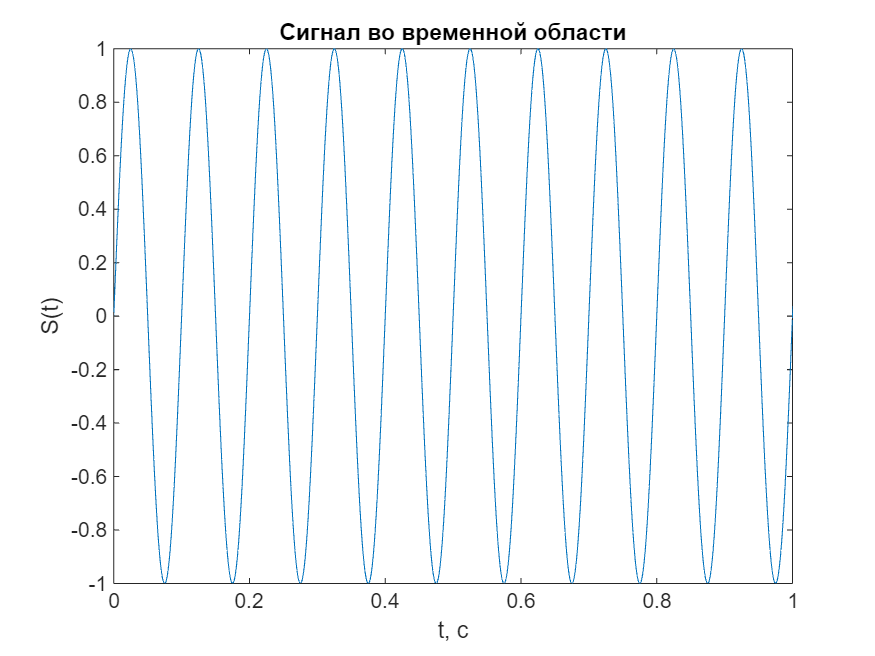

plot(t, S)
title("Сигнал во временной области")
xlabel("t, с")
ylabel("S(t)")
xlim([0, 1])

nA = 1;
nw = 2 * pi * 100;
noise = nA * sin(nw * t);
Sn = S + noise;
S = readlines("C:\Users\cold1\Desktop\dsp 2\putty10hzClean.txt");
noise = readlines("C:\Users\cold1\Desktop\dsp 2\putty100hzClean.txt");
L = min(length(S), length(noise)) - 1;
S = S(2:L);
noise = noise(2:L);
S = str2double(S);
noise = str2double(noise);
S = S / (1024 / 5) - 1.5;
noise = noise / (1024 / 5) - 1.5;
Sn = S + noise;
Sn(10000) = 0;
Sn(10001) = 0;

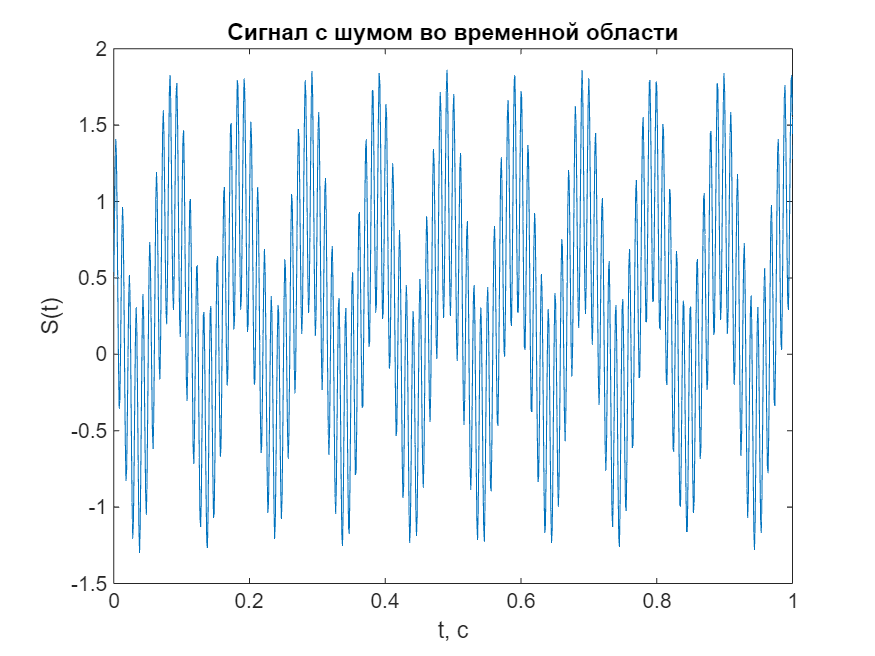

plot(t, Sn)
title("Сигнал с шумом во временной области")
xlabel("t, с")
ylabel("S(t)")
xlim([0, 1])

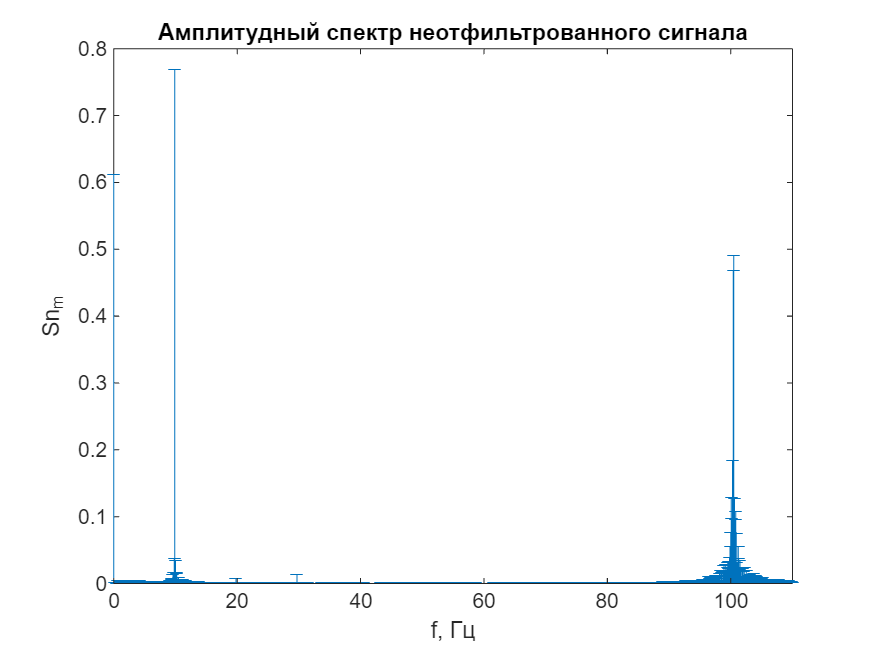

Sn_FFT = fft(Sn);
ampl = abs(Sn_FFT) / length(Sn_FFT) * 2;
crit = max(ampl(2:length(ampl) - 1));
mult = 0.3; % 250-2000 0.15, 10k 0.3, 20k 0.6
ampl_exc = zeros(1, length(ampl));
ampl_exc(ampl > crit * mult) = ampl(ampl > crit * mult);
phase = angle(Sn_FFT);
phase_exc = zeros(1, length(phase));
phase_exc(ampl > crit * mult) = phase(ampl > crit * mult);
stem(f(1 : round(length(f)/2)), ampl(1 : round(length(f)/2)), "Marker","_")
title("Амплитудный спектр неотфильтрованного сигнала")
ylabel("Sn_m")
xlabel("f, Гц")
xlim([0,110])

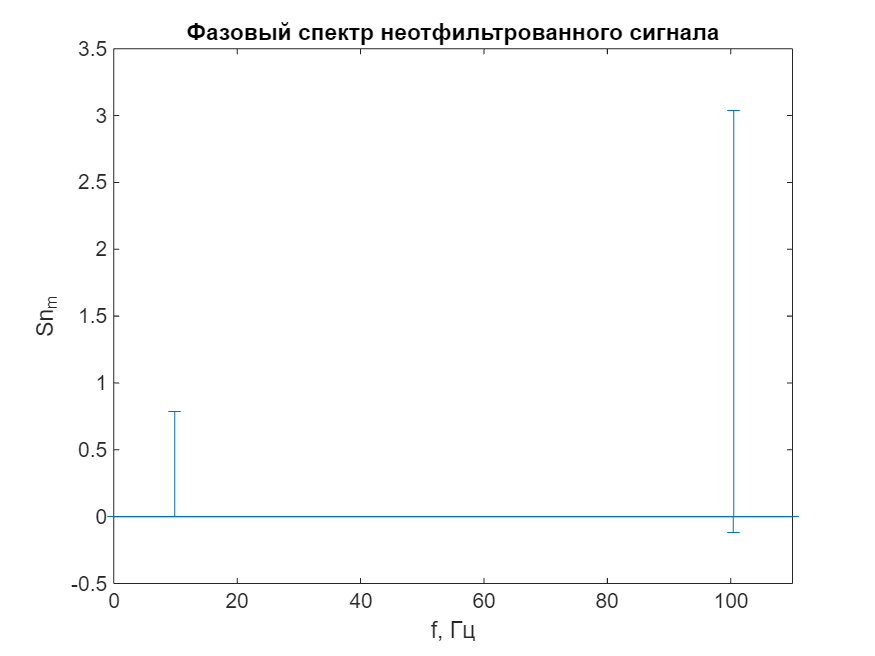

stem(f(1 : round(length(f)/2)), phase_exc(1 : round(length(f)/2)), "Marker","_")
title("Фазовый спектр неотфильтрованного сигнала")
ylabel("Sn_m")
xlabel("f, Гц")
xlim([0,110])

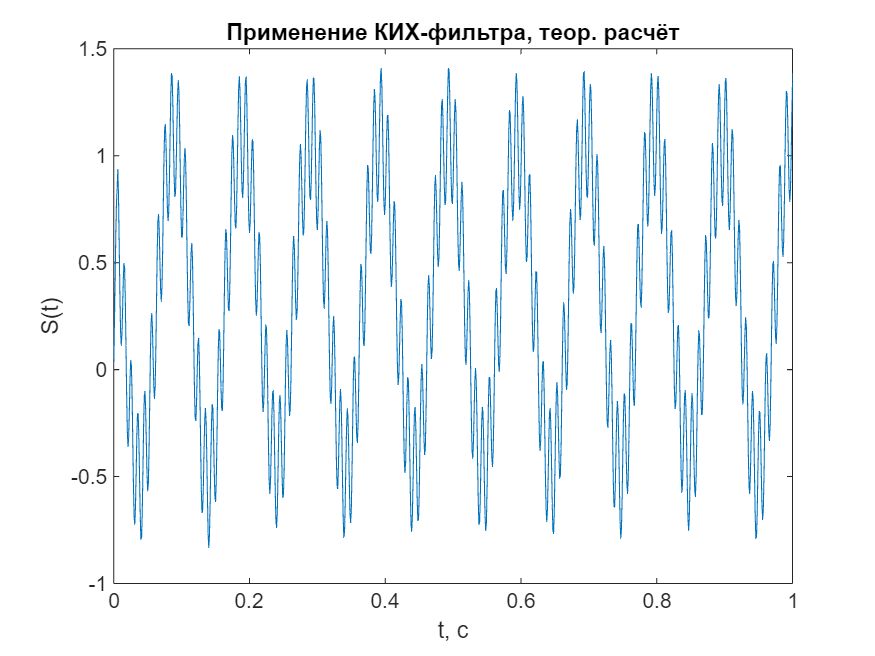

Sfilt = zeros(size(Sn));
for i = 1 : length(Sn)
    for j = 1 : length(fir_nums)
        if i - j >= 1
            Sfilt(i) = Sfilt(i) + fir_nums(j) * Sn(i-j+1);
        end
    end
end
plot(t, Sfilt)
xlabel("t, с")
ylabel("S(t)")
title("Применение КИХ-фильтра, теор. расчёт")
xlim([0,1])

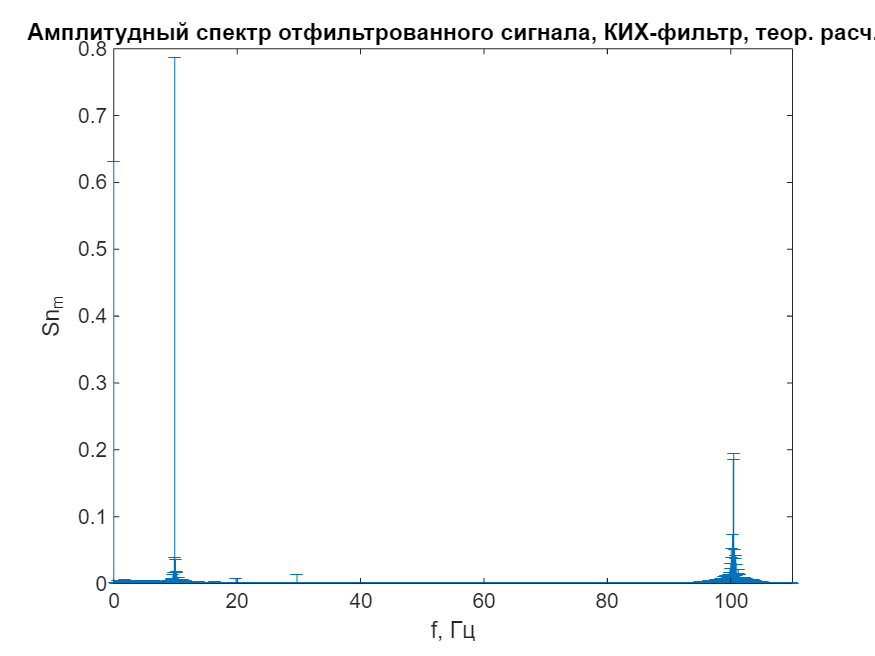

Sn_FFT = fft(Sfilt);
ampl = abs(Sn_FFT) / length(Sn_FFT) * 2;
crit = max(ampl(2:length(ampl) - 1));
mult = 0.3; % 250-2000 0.15, 10k 0.3, 20k 0.6
ampl_exc = zeros(1, length(ampl));
ampl_exc(ampl > crit * mult) = ampl(ampl > crit * mult);
phase = angle(Sn_FFT);
phase_exc = zeros(1, length(phase));
phase_exc(ampl > crit * mult) = phase(ampl > crit * mult);
stem(f(1 : round(length(f)/2)), ampl(1 : round(length(f)/2)), "Marker","_")
title("Амплитудный спектр отфильтрованного сигнала, КИХ-фильтр, теор. расч.")
ylabel("Sn_m")
xlabel("f, Гц")
xlim([0,110])

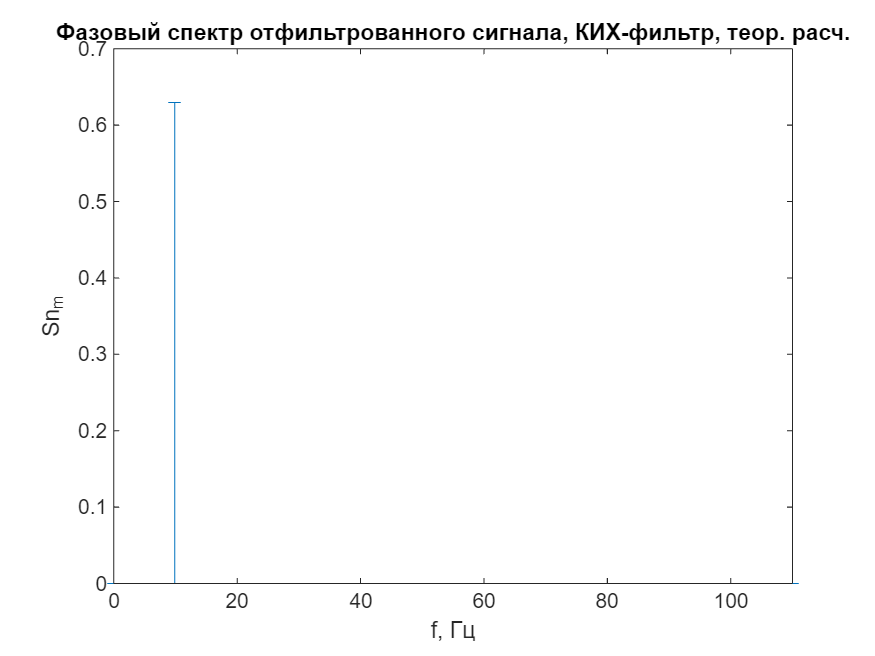

stem(f(1 : round(length(f)/2)), phase_exc(1 : round(length(f)/2)), "Marker","_")
title("Фазовый спектр отфильтрованного сигнала, КИХ-фильтр, теор. расч.")
ylabel("Sn_m")
xlabel("f, Гц")
xlim([0,110])

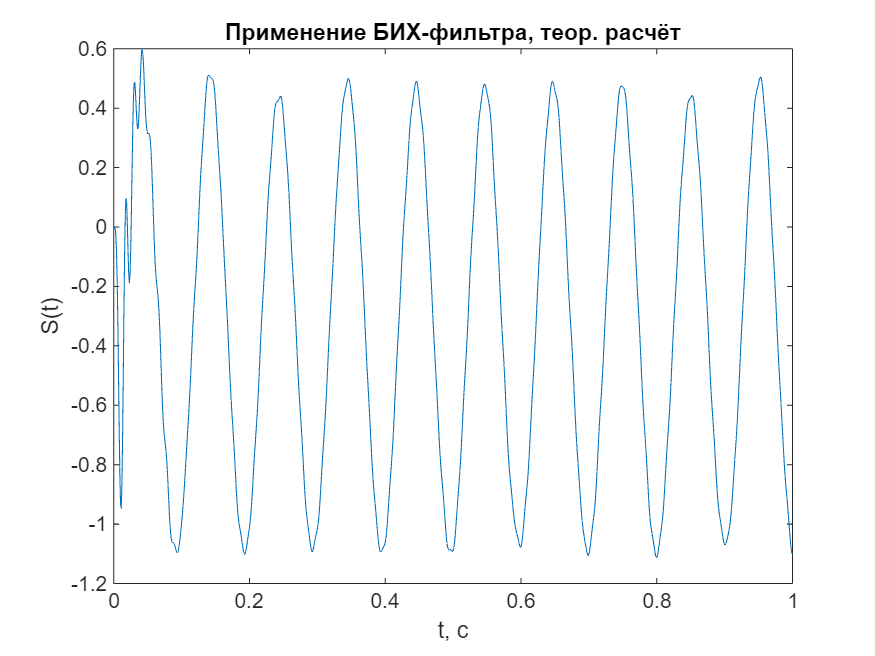

Sfilt = zeros(size(Sn));
for i = 1 : length(Sn)
    for j = 0 : length(a) - 1
        if i - j >= 1
            Sfilt(i) = Sfilt(i) + a(j + 1) * Sn(i - j);
        end
    end
    for j = 2 : length(b)
        if i - j >= 1
            Sfilt(i) = Sfilt(i) - b(j) * Sfilt(i-(j-1));
        end
    end
    
end
plot(t, Sfilt)
xlabel("t, с")
ylabel("S(t)")
title("Применение БИХ-фильтра, теор. расчёт")
xlim([0,1])

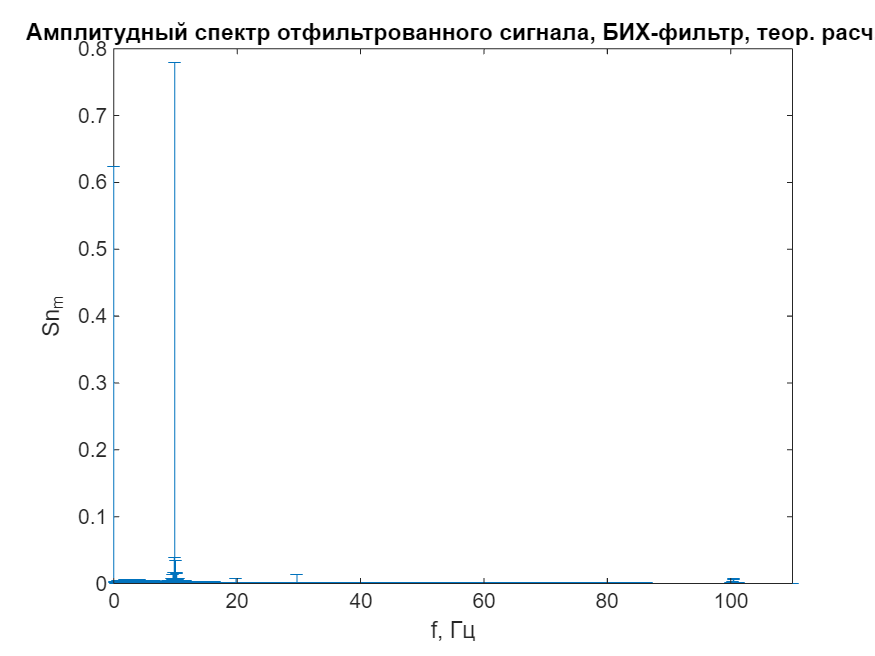

Sn_FFT = fft(Sfilt);
ampl = abs(Sn_FFT) / length(Sn_FFT) * 2;
crit = max(ampl(2:length(ampl) - 1));
mult = 0.3; % 250-2000 0.15, 10k 0.3, 20k 0.6
ampl_exc = zeros(1, length(ampl));
ampl_exc(ampl > crit * mult) = ampl(ampl > crit * mult);
phase = angle(Sn_FFT);
phase_exc = zeros(1, length(phase));
phase_exc(ampl > crit * mult) = phase(ampl > crit * mult);
stem(f(1 : round(length(f)/2)), ampl(1 : round(length(f)/2)), "Marker","_")
title("Амплитудный спектр отфильтрованного сигнала, БИХ-фильтр, теор. расч.")
ylabel("Sn_m")
xlabel("f, Гц")
xlim([0,110])

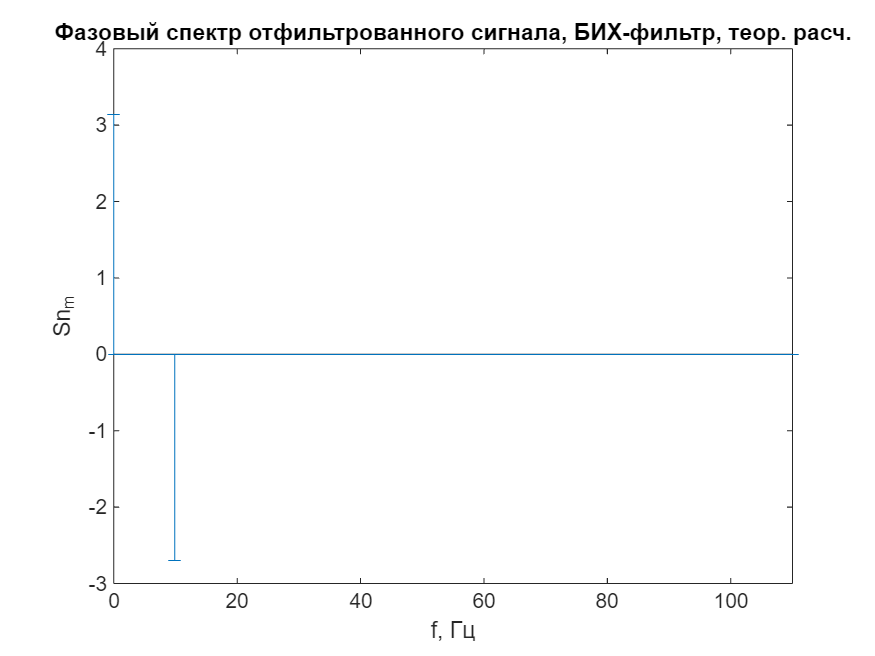

stem(f(1 : round(length(f)/2)), phase_exc(1 : round(length(f)/2)), "Marker","_")
title("Фазовый спектр отфильтрованного сигнала, БИХ-фильтр, теор. расч.")
ylabel("Sn_m")
xlabel("f, Гц")
xlim([0,110])